# Case Study 5: Woburn Toxic Trial

## First Model - steady state groundwater flow

In our first model we will create a 2-D diffusion model of the Woburn superfund site assuming a stead-state confined aquifer with no input or output from wells or surface water. This Live Script document will walk you through the steps of implementing a solution using spatially-centered second-order finite difference operators. Since the model equation does not include any time-variant quantities there is no time loop.  Furthermore, we will solve for all of our model cells at once so there will be no loops over the spatial coordinates either.

*Model Goal*

To assess if contamination would be likely to flow from the potential sources of contaminants to wells G&H.

% add your own descriptive comments

## Define Constants

We will use the following values in our model:

for value = 1:11
% Define Constants
    % Universal
        mu = 1e-4; % viscosity (Pa s)
        rho = 1000; % density (kg/m^3)
        g = 9.81; % acceleration due to gravity (m/s^2)

    % Model Specific
        bedalpha = 0.05.*value; %potential porosity values for basalt (local igneous bedrock)
        tillalpha = 0.25+((.25/11).*value); % potential porosity values of coarse sand from 
        alpha = bedalpha+tillalpha/2;
        k = 1e-11; % permeability in m^2
        T = 15; % original aquifer thickness in m 
        %T = 40; % each layer is maximum thickness
        %T = 9; % each layer is minimum thickness

## Read in data

We will read in the potential pollution source locations and well head (water level) data from csv files.

We have used a couple of different commands to read data into MATLAB (xlsread, load). Another command for importing datat is *importdata()*. This command lets you read in header lines as well as text data values. The data are read into a structure array a data type that groups related data using data containers called *fields*. Each field can contain any type of data. Access data in a field using dot notation of the form `structName.fieldName`.

Use importdata to read in the pollution source locations into a variable named pollutant. The file is comma-delimited (.csv extension) with a single set of column headers.  The syntax for importdata is: Variable = importdata(‘filename’, ‘delimiter’, # headerlines);

% Read in locations of 3 polluted facilities (WR Grace, UniFirst, Riley Tannery(Beatrice)).
sources = importdata("sources.csv", ",", 1); % allows you to input text and numerical data
px = sources.data(:,1); 
py = sources.data(:,2);
sourcename = string(char(sources.textdata{2:4,1}));


Use importdata to read in the data file dec85_data.csv into a variable named data85. The file is comma-delimited (.csv extension) with a single set of column headers.  

% Import well data
data85 = importdata("dec85_metricdata.csv", ",", 1);

% Set variables hx, hy, and h equal to each of the columns of data85.data.
hx = data85.data(:,1);
hy = data85.data(:,2);
h = data85.data(:,3);
WellName = string(char(data85.textdata{:,1})); % convert to character arrays
WellName = WellName(2:end); % removing header value

We will also read in some image data to use for basemaps. The first image is a 2016 aerial image and the second is a 2014 lidar DEM.

FilenameImg = '2016_4BandImagery.tif';
[A,R] = readgeoraster(FilenameImg);
Aerial = flipud(A(:,:,1:3)); % take RGB bands
% create x and y vectors for cell centerpoints
x = R.XWorldLimits(1)+R.CellExtentInWorldX/2:R.CellExtentInWorldX:R.XWorldLimits(2)-R.CellExtentInWorldX/2;
y = R.YWorldLimits(1)+R.CellExtentInWorldY/2:R.CellExtentInWorldY:R.YWorldLimits(2)-R.CellExtentInWorldY/2;

%convert x and y to meters
xImg = x/3.28084;
yImg = y/3.28084;

FilenameDEM = 'coned_new_england_dem.tif';
[A,R] = readgeoraster(FilenameDEM);
DEM = flipud(A); % change from image to xy coordinates

% create x and y vectors for cell centerpoints
x = R.XWorldLimits(1)+R.CellExtentInWorldX/2:R.CellExtentInWorldX:R.XWorldLimits(2)-R.CellExtentInWorldX/2;
y = R.YWorldLimits(1)+R.CellExtentInWorldY/2:R.CellExtentInWorldY:R.YWorldLimits(2)-R.CellExtentInWorldY/2;

%convert x and y to meters
xDEM = x/3.28084;
yDEM = y/3.28084;



Create a two-part figure with image and DEM basemaps using *subplot(row, column, number).*

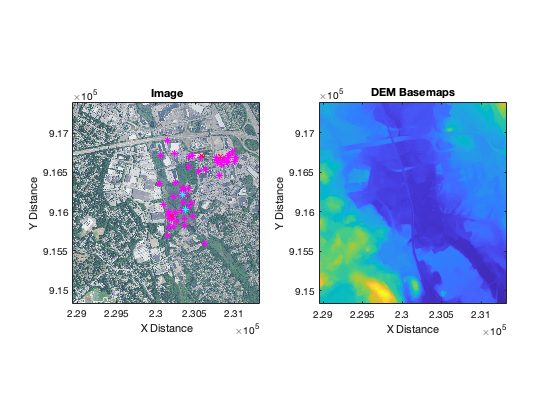

figure(1)
subplot(1,2,1)
imagesc(xImg,yImg,Aerial)
axis equal tight xy
xlabel("X Distance")
ylabel("Y Distance")
title("Image")

subplot(1,2,2)
imagesc(xDEM,yDEM,DEM)

axis equal tight xy
xlabel("X Distance")
ylabel("Y Distance")
title("DEM Basemaps")

% plot wells and potential pollution sites
subplot(1,2,1)
hold on
plot(hx,hy,"m*")
%text(hx,hy, WellName)
plot(px,py,"rx")
plot(hx(1:2),hy(1:2),"c*") % these are where the drinking water came from

Add your well data (black star) and the pollution sites (red x) on to each map using *subplot* and *hold*. Use t*ext()* to label each well.

## Defining the model domain

We will use the distribution of the wells and their head values to define our model domain and boundary conditions, respectively.

We'll begin with a 50-m cell size, and refine later

Now we want to create a grid of cells  that spans the data.  We will do this using the command `[X,Y] = meshgrid(x,y)`, which creates two arrays filled with the x and y values of the domain specified by the vectors x and y.  In our case we want the grid to span the minimum to maximum value of each spatial coordinate (x,y) in increments of our cell size variables.  We can use the commands `min(variable)`and `max(variable)` where variable is replaced with the appropriate well coordinate variable to define the start and end of our model dimension vectors (x and y).

Now we want to interpolate the head values, h to fill the grid with initial estimates (which will form our boundary conditions at the edge of our grid).  We will use the command F = `scatteredInterpolant`(hx, hy, h) to create a linear interpolation of the well coordinate (hx,hy) and head (h) values.

In order to create our mesh of initial values we then need to apply the resulting function, F to our X and Y arrays created above using the syntax Hi = F(X,Y);.

We now need to find a rectangular area that contains interpolated values.  Ideally we want the largest possible area that puts our sites of interest within the model domain (not at the boundaries). This can be done in a computer code, but it’s not an easy solution (for example see FindLargestRectangle on Matlabcentral).  However, our eyes and brain are pretty good at solving this sort of problem so we’ll plot the initial surface and pollutant sites and manually identify our model region.  A quick way to visualize an array is to create a scaled image of the data.  We can use the command `imagesc(X(1,:),Y(:,1),Hi)`to do this with x,y coordinates specified in the row and column of the X and Y arrays.  Then plot the pollutant and well G&H locations as symbols to visualize the area of interest.

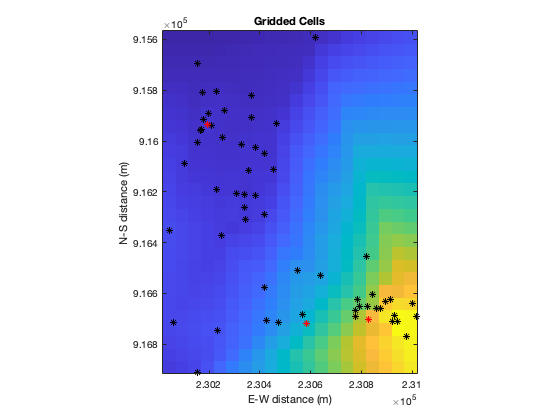

% define cell dimensions (dx, dy)
dx = 50;
dy = 50;

% create our mesh of grid cells covering the region where we have data
[X,Y] = meshgrid(min(hx):dx:max(hx), min(hy):dx:max(hy));

% interpolate the head values across our grid of cells
    % create interpolation function from well data
    F = scatteredInterpolant(hx, hy, h, "linear");
    % use interpolation function to interpolate values for each of model cell
    Hi = F(X,Y); % initial/boundary conditions


% plot the results to define our area of interest
figure
imagesc(X(1,:),Y(:,1),Hi)

hold on
axis equal tight 
plot(hx,hy,"k*")
plot(px,py,"r*")
% add axis labels
xlabel("E-W distance (m)")
ylabel("N-S distance (m)")
title("Gridded Cells")

Choose your rectangular area of interest and write commands to reduce each of your original arrays (X, Y, Hi) to the new region (e.g. Hi = Hi(#:end-#, #:end-#) where the number signs represent the rows and columns you wish to remove from the edges.  You have now defined your model domain and boundary conditions. After cropping you will want to change  your image to map coordinates using the command *image xy*.

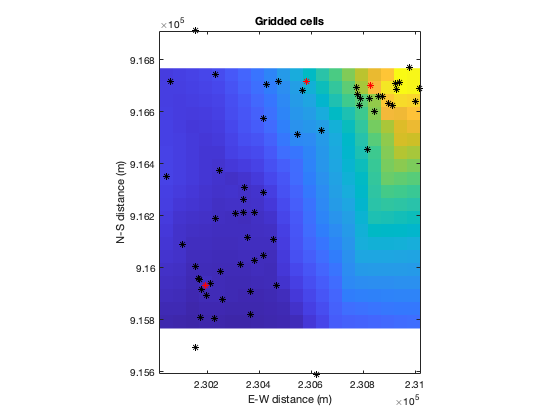

% crop the grids to the area of interst (note these commands will
% change if you change your cell size).
X = X(5:end-3, 1:end); % clip off rows or columns, this can be edited
Y = Y(5:end-3, 1:end);
Hi = Hi(5:end-3, 1:end);


figure
imagesc(X(1,:),Y(:,1),Hi)

hold on
axis equal tight xy
plot(hx,hy,"k*")
plot(px,py,"r*")
% add axis labels
xlabel("E-W distance (m)")
ylabel("N-S distance (m)")
title("Gridded cells")

## Second draft - adding a well

In our first draft model we assumed that there were no additional sources/sinks. We will now modify that model to add boundary conditions that simulate pumping at wells G&H. You will need to modify your initial model with lines of code from this assignment.

It is estimated that the wells, G and H, were pumped at 800, and 400 gal/min, respectively (T. J. Merin as cited in de Lima and Olimpio, 1989).  We will use these well pumping rates to calculate steady-state conditions (ie long term pumping).  We will compare our model to the transient head values the USGS measured after a 30-day pump test in January 1986.

For our base model we created a matrix of zeros that we called Q.  We will replace some of these zeros with new values to simulate well flow as a sink term (additional boundary condition).

## Adding the well data

***(add to a copy of your week 1 script  after "Defining thFIe model domain" in first week script)***

If you haven't already done so you will need to define your well x,y coordinates. Wells G&H are the first two lines in each of the data files. Create new variables to store there x and y locations.

Next we need to add a variable that contains the well flow rates.  We will call this Qpump.  Our model equation expresses wells in their flow rate per model cell volume so not only do we need to convert gal/min to m^3/s (there are 264.172 gal/m^3), but we also need to divide by our cell volume in m^3.  Make Qpump a 1x2 vector so that you can save both wells' flow rates.

% create well location vectors (xwell, ywell) with x and y values for wells G&H
xwell = data85.data(1:2,1);
ywell = data85.data(1:2,2);

% add rates for wells G&H to vector Qpump
Qpump = zeros(1,2); 
Qpump(1) = 1000/264.172/60/(dx*dy*T);
Qpump(2) = 600/264.172/60/(dx*dy*T);
% convert gal/min to M^3/s and divide by cell vol

## Set up the numerical solution to solve for the steady-state flow

***Building the A matrix***

First we will build a matrix to store the coefficients from the left hand side of our finite difference equation.

The A matrix will store the coefficients for the finite difference equations for all of the interior cells.  If the model space is of dimensions m x n then the dimensions of A will be (m-2)*(n-2) x (m-2)*(n-2).  Since the equation only uses the value at the given cell (i,j) and its immediate neighbors there will be many empty (zero) cells.  The filled values will be located along 5 diagonals within the matrix (a tri-diagonal matrix). We will build the matrix by filling each of these diagonals.

Note that all the coefficients will be divided by 1/dx^2 or 1/dy^2 it is easier to create variable for these terms rather than constantly typing them.  We’ll call them r and s, respectively.

Calculate the number of interior x and y cells (intervals, xints and yints) within the model (ie dimensions -2) using the built-in MATLAB function size(W,dimension).

The main diagonal of the A matrix is filled with the (i,j) coefficients (-2r-2s) and is of length (m-2)*(n-2) or xints* yints.  The MATLAB command for building a diagonal matrix is `A=diag(V,K)`where V is a vector of the diagonal values and K specifies the diagonal to be filled (0 is the main diagonal, +1 is the diagonal above this, -1 is the diagonal below, and so on…).  Use `(-2*r-2*s)*ones(xints*yints,1)` to build your vector and place it on the main diagonal.

Continue with the diagonal above and below which will have one less element and will store the coefficients for the i+1, j and i-1,j terms respectively.

The last two diagonals are a bit trickier. They store the i, j+1 and i, j-1 terms.  These cells are not immediately above and below the i,j  cell in our matrix, but rather are removed by the number of columns (xints) in the matrix.  We therefore want to place these coefficients in the +/-xints diagonals, which have a length of xints*yints-xints (or xints*(yints-1)).

Finally, we need to zero out the r coefficients on the boundary elements as these will be treated in our boundary value vector.  This piece of code is written for you.

% build the A matrix
    % define r and s coefficients
    r = 1/dx^2;
    s = 1/dy^2;

% we are going to flatten the whole space, so we need to know how many xs
% and ys are in the domain

    % define x and y intervals (xints and yints)
    xints = size(X,2) - 2; % number of x intervals minus boundaries
    yints = size(Y,1) - 2;
    
    % make the tri-diagonal matrix filled with the appropriate coefficients
    A = diag((-2*r-2*s).*ones(xints*yints,1))... % main diagonal
      + diag((r)       .*ones(xints*yints-1,1),1)... % one above the main diagonal (superdiagonal)
      + diag((r)       .*ones(xints*yints-1,1),-1)... % subdiagonal
      + diag((s)       .*ones(xints*yints-xints,1),xints)... % cell above the equation we are defining?
      + diag((s)       .*ones(xints*yints-xints,1),-xints); % cell below
    % zero out the "r" components at the boundaries
        for i=1:yints-1
            A(i*xints,i*xints+1)=0; % right side
            A(i*xints+1,i*xints)=0; % left side
        end
        

***Building the b vector***

Now we will build the vector of boundary conditions, b.  This vector will store the coefficients for boundary cells as well as any well flow rates (later).  We will take a more physical approach to building this vector by building it in matrix form and then transforming it into a vector.

Create an M matrix that stores our well values (the right hand side of the equation).  For now these will all be zeros, but in week 2 we will add pumping wells.  First create a matrix Q of zeros the size of our model (X).  Next create a matrix M equal to Q (next week we will calculate values of M from Q).

Now we will create our boundary value matrix (B).  It will be of dimension m-2 x n-2.  We want to start by filling it with the appropriate values from the M matrix.  Use index commands to set B equal to the interior cells of M.

% build the b vector


    % create the empty Q and M matrices
    Q = zeros(size(X));
    M = Q; 

    

## Modifying the Q, M and B matrices

***(add to your week 1 script after creating the empty Q matrix)***

In our original code we built a Q matrix of zeros and set the M matrix equal to the Q matrix. In this section we will modify that code to put the well pumping values (normalized by cell volume above) into the appropriate locations in the Q matrix and then calcualte the M values from the Q values. Our orignal code then uses this M matrix as the starting point for the B matrix.

1. First we will test if there are wells in the script so that we can run the script with or without wells. To do this we will create an “if” statement conditional on the result of the command `exist('A','var')`where 'A' is one of your well-realted variables (e.g., xwell) and 'var' tells the function that you are testing for the presence of a variable.

2. Within this “if” statement (i.e., before the end) we will create a `for` loop that loops over the number of pumping wells.

3. Within the `for `loop we will find the cells that contain each well. We do this by finding the index of the closest column in the x direction and the index of the closest row in the y direction. This requires two statements (one for each Cartesian coordinate) of the form: `[~, pos]=min(A)` where A is the absolute value, `abs()`, of the difference between the coordinates of the cell centers (X or Y) and the well’s coordinate values (xwell or ywell).  The ~ here tells MATLAB to simply ignore this output, which in this case is the actual coordinate value of the closest cell.  Instead we will only keep the index value in the resulting variable. You may want to name these xpos and ypos.

4. Once you have your two indices you can set the corresponding value of the Q matrix to the appropriate well pump rate.

Remember to end your loop and if statements.

Now we need to add a definition of the M matrix (replacing command M = Q from week 1).

From our discussion of the modified balance we determined that the m term for a well should be eqal to:


$$\frac{\mu*Q}{\alpha*k*\rho*g}$$


Calculate M from Q using this equation.

% OPTIONAL
    
% 1. Use if statement to check for well data. If present...

% 2. Loop over each well with pumping rate data.

% 3. Find the indices of the closest cell center in the x and y directions

% 4. Replace the 0 in Q matrix with apropriate value from your Qpump vector.

for j = 1:length(xwell)

    % find which cells the wells are in
    [~,xpos] = min(abs(X(1,:)-xwell(j)));
    [~,ypos] = min(abs(Y(:,1)-ywell(j)));
    Q(ypos,xpos) = Qpump(j);
end

    % Calculate M from Q
M = (mu.*Q)./(alpha*k*rho*g);
    

Your definition of the M matrix should now calculate the appropriate value of the right-hand side of the equation for these M values, which will then be used as the starting values for our boundary condition matrix, B.  The wells will thus be included in your solution when you run your model.

Now we want to add the appropriate terms to each boundary.

For the first column `B(:,1)` we want to subtract the h(i-1,j) term.  We can calculate this term for all the left boundary elements with the formula r`*Hi(2:end-1,1)`.

Similarly for the last column `B(:,end)` we want to subtract the h(i+1,j)term.

For the first row of B we need to subtract the h(i,j-1) term (Y counting down).We can calculate this term for all the southern boundary elements with the formula s*Hi(1,2:end)

And finally we subtract the h(i,j+1) term from the last row.

Now we need to convert our matrix of boundary values to a vector.  `b=B(:)` will create a vector b containing all the elements of B taken column by column. We want to take the values row by row so first we must transpose B using the command `B=B’`. 

% create B matrix from interior of M matrix
    B = M(2:(end-1),2:(end-1)); % crop off the edges

    % subtract the r term from the first column
    B(:,1) = B(:,1) - r*Hi(2:end-1,1);

    % subtract the r term from the last column
    B(:,end) = B(:,end) - r*Hi(2:end-1,end);

    % subtract the s term from the first row
    B(1,:) = B(1,:) - s*Hi(1,2:end-1);

    % subtract the s term from the last row
    B(end,:) = B(end,:) - s*Hi(end,2:end-1);

    % transpose and convert to vector
    B = B';
    b = B(:);

## Solving the inverse problem

Now we are ready to solve the inverse problem to determine the vector of hydraulic head (water table) values for each of our grid cells.

Calculate our model head values (hhat) using A\b (mldivide)

Use the command `Hhat=reshape(X,M,N) `to change the head vector into a matrix of dimensions m x n where m is the number of x intervals and n is the number of y intervals.

We need to append our boundary values (stored in Hi) onto our model (stored in Hhat).  To do this: create a variable called solution equal to Hi, then replace the central values with Hhat. 

% Solution
    %solve for model head vector hhat
    hhat = A\b; % left matrix divide

    % reshape into matrix Hhat
    Hhat = reshape(hhat,xints,yints); % matrix version
    Hhat = Hhat';

    % patch into boundary values
    solution = Hi;
    solution(2:end-1,2:end-1) = Hhat;
   

## Visualize your solution

Create a figure with two side-by-side subplots

In the first subplot we will create color-filled contours of hydraulic head across the model area, add streamlines, and plot the real data for comparison.

To create color-filled contours we will use the command `[C,H] = contourf( X,Y,solution)`.  C contains the contour values and H is the handle that would let us address this figure later if we wish.  The command `clabel(C,H)`the labels the contour values. `axis equal tight` makes the x and y scales equal and crops the axes to the data.  `hold on` retains the figure for further plotting.  `colorbar(‘West’)`creates a colorbar on the left side of the figure (is there a better place?)

To create streamlines to represent particle paths we will calculate the gradients using `[FX,FY] = GRADIENT(F,HX,HY)` substituting our solution and interval values for F and H terms respectively.  We can then plot the streamlines using H= STREAMLINE(X,Y,U,V,STARTX,STARTY) where U and V are the gradients*-1 (since water flows downhill) and the start coordinates are for the polluted sites.  Finally set the streamline properties to bold red using `set(H,’color’,’r’,’linewidth’,2)`.

Plot the well data as black points and add labels for the head elevation using `text(hx,hy,num2str(h))`. Where num2str converts the head numerical values into text strings.

Label your axes and we’re done with the first plot.

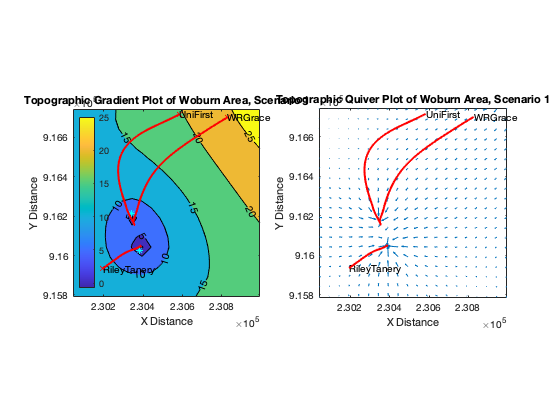

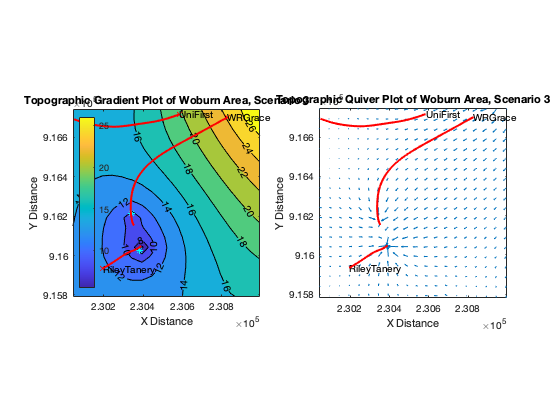

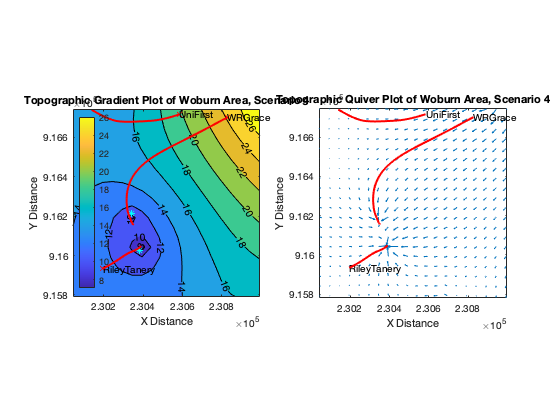

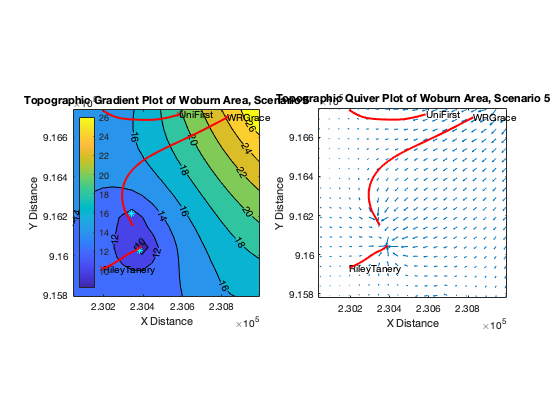

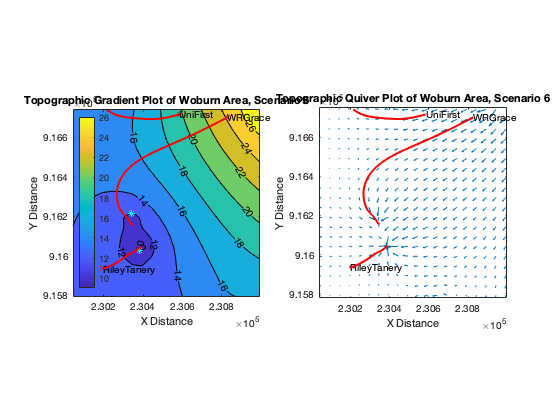

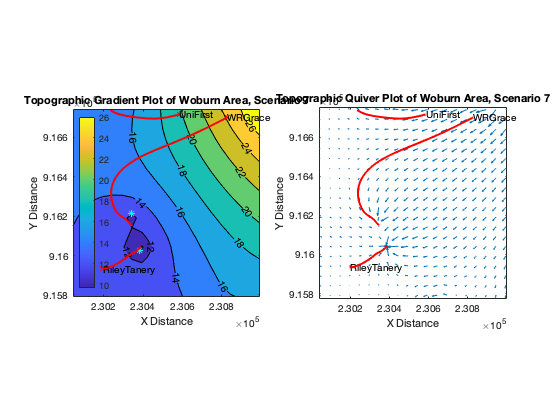

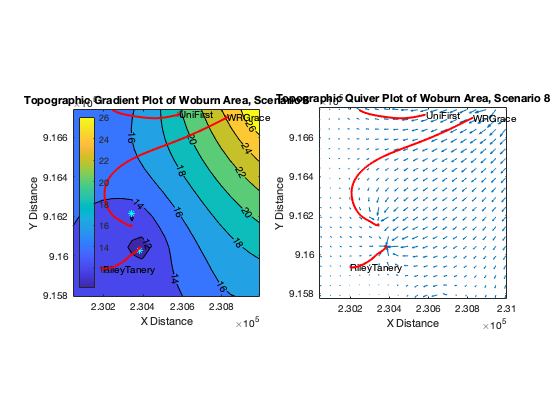

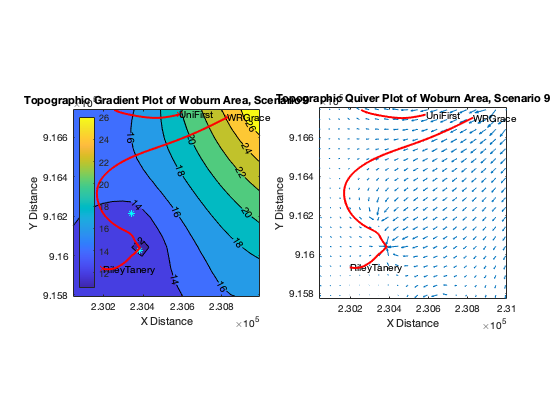

% Visualize results
    % subplot for color contours
    figure 
    set(gcf,'color','w')

    subplot(1,2,1)

    % plot color contours with labels
    [C,handle] = contourf(X,Y,solution);
    clabel(C,handle)
    axis equal tight 
    hold on
    colorbar('West')

    % plot(hx,hy,"m*")
    % text(hx,hy, WellName)
    plot(px,py,"rx")
    text(px,py, sourcename)
    
    plot(hx(1:2),hy(1:2),"c*")
    axis equal tight 

    % calculate gradients
    [partx,party] = gradient(solution, dx, dy);

    % plot streamlines from pollution sites
    h1 = streamline(X,Y,-partx,-party,px,py); % px,py are the potential pollution sites
    set(h1, 'color','r','linewidth',2);

    xlabel("X Distance")
    ylabel("Y Distance")
    titlesame = append ("Topographic Gradient Plot of Woburn Area, Scenario ", num2str(value));
    title(titlesame)
    

For the second subplot we will create arrows of flow direction and add the streamlines again.

To create flow direction arrows we will use the command `quiver(X,Y,-px,-py)`. If you want bigger arrows add a scale factor at the end.

Hold the plot

Add streamlines as we did before.

Add well data

Fix up the axes and add labels.

        % subplot for flow directions
        subplot(1,2,2)

        % plot arrows in the direction of flow
        quiver(X,Y,-partx,-party)
        hold on
        text(px,py, sourcename)

        % plot streamlines from pollution sites
        h1 = streamline(X,Y,-partx,-party,px,py);
        set(h1, 'color','r','linewidth',2);

        axis equal tight

        jawn = num2str(value);
        titlename = append ("Topographic Quiver Plot of Woburn Area, Scenario ", num2str(value));

       xlabel("X Distance")
       ylabel("Y Distance")
       title(titlename)

        % DONT FORGET TO ADD LABELS

        % quiver plot shows the direction of flow, and the flow rate
        % (longer arrows are higher rates of flow, steeper gradients)

end

## Questions

- How well does your model fit the data? (can you quantify this? Hint: doc griddedInterpolant)

In order to compare the well data to our model we need to interpolate the model values, which are reported for each grid cell to the well locations.  We can do this in MATLAB using the command `hhat = interp2(X,Y,solution,xwell,ywell)`where hhat are the interpolated  head values, X, Y, and solution are the model coordinate arrays and the model head solution and xwell, ywell are the coordinates for the wells in the 1986 data file.

Note that some of the wells may fall outside of our model area.  These will return no data values (`NaN`) in the interpolation. In the following step you should use the logical operator `isfinite(hhat)` to extract only the wells that are within the model space.  For example, to find the model head values for wells within the model space you would type `hhat(isfinite(hhat))`. You may want to assign these to a new variable.   Similarly, if you put the `isfinite` statement in parentheses after your well head variable you will get the observed head for all locations within the model domain using logical indexing.

hhat = interp2(X,Y,solution,xwell,ywell);


- Based on this model would you expect that the contamination from the sites would have reached the wells? Answer for each facility.  Who appears most likely to be responsible for the contamination?

- Review the model assumptions.  Is each appropriate for the site?